Stacked graphs

Now reading Peterpan\PP_1.mat


Now reading Peterpan\PP_10.mat


Now reading Peterpan\PP_2.mat


Now reading Peterpan\PP_3.mat


Now reading Peterpan\PP_4.mat


Now reading Peterpan\PP_5.mat


Now reading Peterpan\PP_6.mat


Now reading Peterpan\PP_7.mat


Now reading Peterpan\PP_8.mat


Now reading Peterpan\PP_9.mat


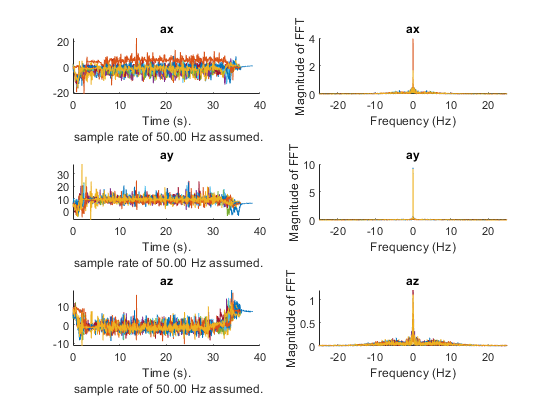

myDir = "Peterpan"; %gets directory with 180 files
myFiles = dir(fullfile(myDir,'*.mat')); %gets all .mat files in struct
for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    [push] = ParseMatlabApp(fullFileName);
    t = push.t_Accel; 
    accel = push.Accel;
    ax = accel(:,1);
    ay = accel(:,2);
    az = accel(:,3);
    Fs = 50;
    N = size(accel);
    N = N(1);
    f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    
    subplot(3,2,1)
    hold on
    
    make_time_plot(ax, Fs, 'ax')
    subplot(3,2,2)
    hold on
    make_freq_plot(ax, Fs, 'ax')
    
    subplot(3,2,3)
    hold on
    make_time_plot(ay, Fs, 'ay')
    subplot(3,2,4)
    hold on
    make_freq_plot(ay, Fs, 'ay')
    
    subplot(3,2,5)
    hold on
    make_time_plot(az, Fs, 'az')
    subplot(3,2,6)
    hold on
    make_freq_plot(az, Fs, 'az')
      % all of your actions for filtering and plotting go here
end

Individual graphs

Now reading Peterpan\PP_1.mat


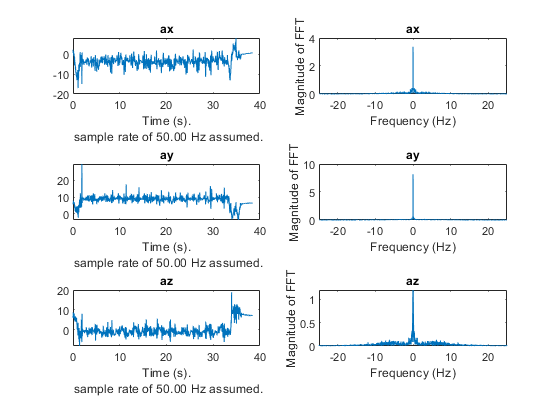

Now reading Peterpan\PP_10.mat


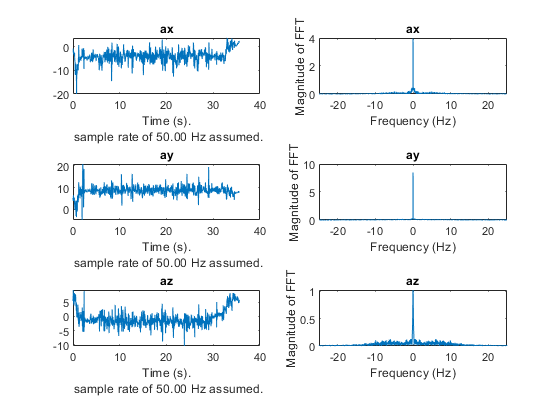

Now reading Peterpan\PP_2.mat


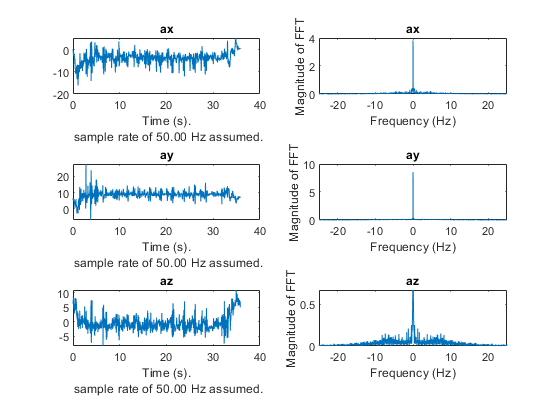

Now reading Peterpan\PP_3.mat


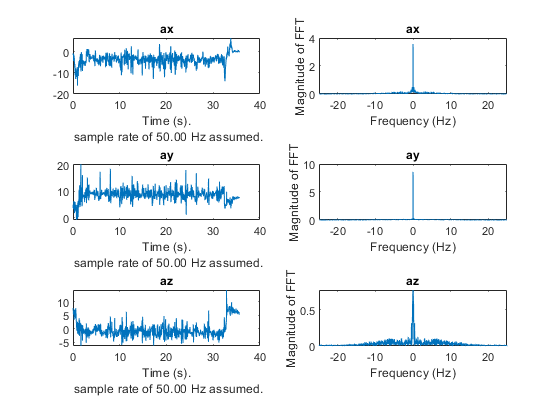

Now reading Peterpan\PP_4.mat


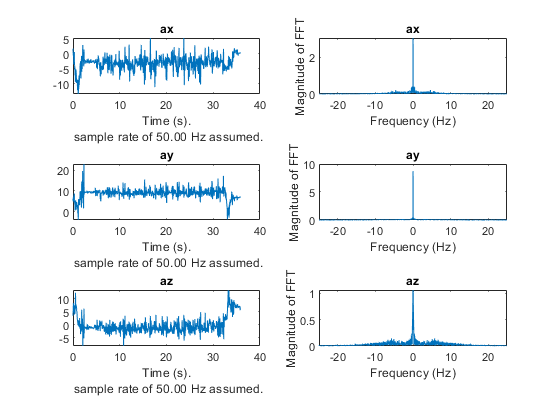

Now reading Peterpan\PP_5.mat


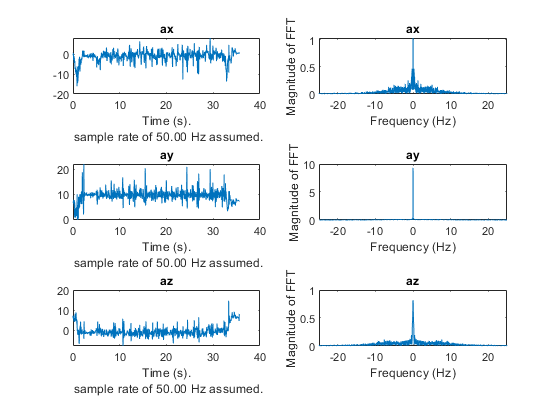

Now reading Peterpan\PP_6.mat


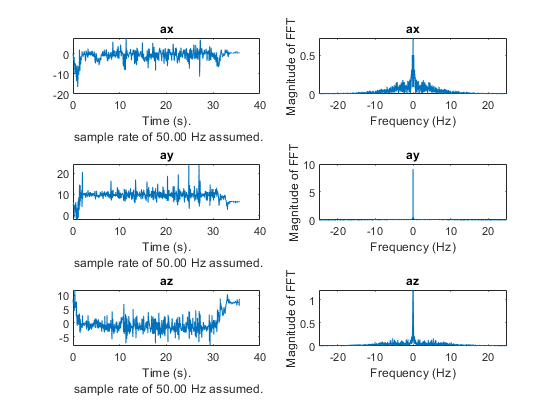

Now reading Peterpan\PP_7.mat


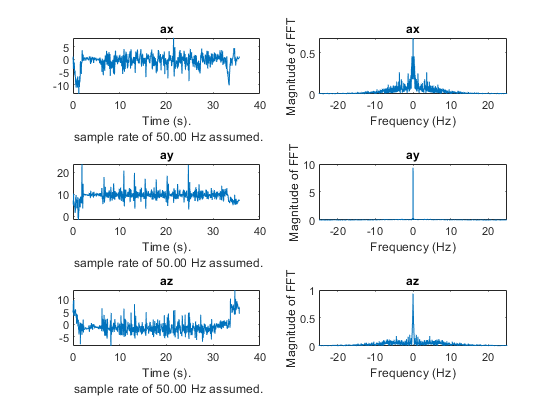

Now reading Peterpan\PP_8.mat


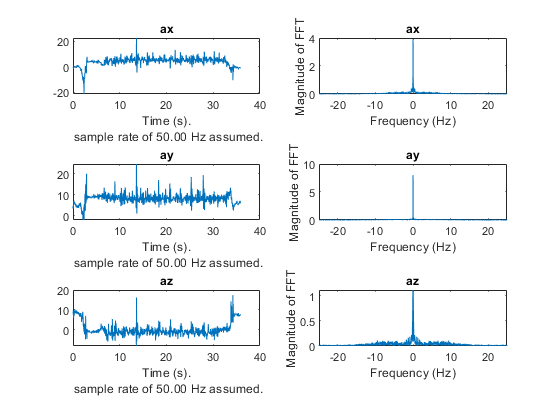

Now reading Peterpan\PP_9.mat


myDir = "Peterpan"; %gets directory with 180 files
myFiles = dir(fullfile(myDir,'*.mat')); %gets all .mat files in struct
for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    
    [push] = ParseMatlabApp(fullFileName);
    t = push.t_Accel; 
    accel = push.Accel;
    ax = accel(:,1);
    ay = accel(:,2);
    az = accel(:,3);
    Fs = 50;
    N = size(accel);
    N = N(1);
    f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);
    figure
    hold on
    subplot(3,2,1)
    
    make_time_plot(ax, Fs, 'ax')
    subplot(3,2,2)
    make_freq_plot(ax, Fs, 'ax')
    
    subplot(3,2,3)
    make_time_plot(ay, Fs, 'ay')
    subplot(3,2,4)
    make_freq_plot(ay, Fs, 'ay')
    
    subplot(3,2,5)
    make_time_plot(az, Fs, 'az')
    subplot(3,2,6)
    make_freq_plot(az, Fs, 'az')
      % all of your actions for filtering and plotting go here
end

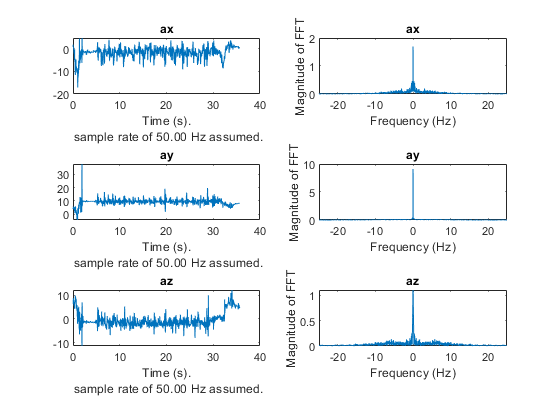

hold off